# ICEL9 Data Analysis Workshop

MATLAB version - J.I.M. Parmentier, collaboration with Christoffer Roepstorff

Utrecht University - August 2023

## Skeleton of the assignment - part 2 (Looking at all files, T0)

- Declare the datapath and different needed information (e.g., horses identifiers, markers of interest) 

- In a loop, load the files and extract the parameters file by file as defined in the assignement part 1 (and some variations, for example in the stride splitting section)

- Remove outliers, based on impossible stride duration values

- Save the parameters in a table (e.g., csv file) for future analysis

- Compare the results between horses

## I. Load the data and declare the variables of interest

To load the data, you need to first define a datapath. You can copy-paste below where your data is located:

clear all; close all; clc;

results = table(NaN,NaN,NaN,NaN,NaN,NaN,NaN,{''},{''});
results.Properties.VariableNames  = {'StrideDuration',...
        'MinDiff_Head','MaxDiff_Head',...
        'MinDiff_Withers','MaxDiff_Withers',...
        'MinDiff_Pelvis','MaxDiff_Pelvis',...
        'HorseID','TimePoint'};

datapath = '.\data';

In this section, we will work with the data of horse A at timepoint T0 only. You can define this in the following HorsesList variable:

HorsesList = {'horseA','horseB','horseC','horseD','horseE','horseF','horseG',...
    'horseH','horseJ','horseK','horseL','horseM','horseN','horseO'};
TimePointsList = {'T0'};

We will work with three upper-body markers: Head ('Poll'), Withers ('T8') and the Pelvis ('TubSac'). You can define them below:

MarkersUpperBody = {'Poll','T8','TubSac'};
MarkersNames = {'Head','Withers','Pelvis'};

For splitting the data into strides for the analysis, we will use the left hind hoof ('Hoof_LH') only.

MarkersStrideSplit = {'Hoof_LH'};

You can now look for your data file and load it!

files = dir(strcat(datapath,'/',TimePointsList{1},'_*','_trot1.mat'));

if ~isempty(files)
    uiwait(msgbox('Congratulations! You found a file. We are downloading it for you.'));
else
    errordlg('We could not find a file. Please check your datapath, horse name and time point name.',...
        'File Error');
end

We have found all the files. Now, within a loop, we are going to process them one by one and extract all the data! 

## II. Loop through the files

To help with the missing samples, we have already manually defined which segments to use. You can read the csv file with the information.

segmentTimestamps = readtable('.\data\timestamps.xlsx');

for i_file = 1:length(files)
    Data = load([files(i_file).folder,'/',files(i_file).name]);
    HorseID = erase(files(i_file).name,{'_trot1.mat','T0_horse'});
    TimePoint = 'T0';
    
    ind = find(strcmp(segmentTimestamps.Pony, HorseID)==1 & strcmp(segmentTimestamps.Timepoint,TimePoint)==1);
    
    segment_start = segmentTimestamps.start(ind); segment_stop = segmentTimestamps.stop(ind); ind = [];

    %% Extract the trajectories
    Trajectories = permute(Data.trot1.Trajectories.Labeled.Data,[3, 2, 1]); % 3D displacements data

    MarkersName = Data.trot1.Trajectories.Labeled.Labels; % Markers names
    Fs = Data.trot1.FrameRate; % Sampling frequency, in Hz
    Time = 0:1/Fs:(Data.trot1.Frames-1)/Fs; % Creating a Time vector

    ind_head = find(strcmp(MarkersName , MarkersUpperBody{1})==1); % Poll
    ind_withers = find(strcmp(MarkersName , MarkersUpperBody{2})==1); % T8 (Withers)
    ind_pelvis = find(strcmp(MarkersName , MarkersUpperBody{3})==1); % Tubera Sacrale (Pelvis)

    ind_LHhoof = find(strcmp(MarkersName , MarkersStrideSplit{1})==1); % LH Hoof

    Head_data = Trajectories(:,:,ind_head); % Poll
    Withers_data = Trajectories(:,:,ind_withers); % T8
    Pelvis_data = Trajectories(:,:,ind_pelvis); % Tubera Sacrale
    LHHoof_data = Trajectories(:,:,ind_LHhoof); % LH hoof
  
    %% Extract the defined segment
    [~,beginning_ind] = min(abs(Time-segment_start));
    [~,end_ind] = min(abs(Time-segment_stop));

    Extracted_Time = Time(beginning_ind:end_ind);
    Extracted_Head_data = Head_data(beginning_ind:end_ind,:);
    Extracted_Withers_data = Withers_data(beginning_ind:end_ind,:);
    Extracted_Pelvis_data = Pelvis_data(beginning_ind:end_ind,:);
    Extracted_LHHoof_data = LHHoof_data(beginning_ind:end_ind,:);
 
    % Plot
    figure
    ax(1) = subplot(211);
    plot(Extracted_Time,Extracted_Head_data(:,3)- mean(Extracted_Head_data(:,3))); hold on
    plot(Extracted_Time,Extracted_Withers_data(:,3)-mean(Extracted_Withers_data(:,3)));
    plot(Extracted_Time,Extracted_Pelvis_data(:,3)-mean(Extracted_Pelvis_data(:,3)));
    legend('Head','Withers','Pelvis');
    xlabel('Time (s)');
    ylabel('Vertical displacement (mm)');

    ax(2) = subplot(212);
    plot(Extracted_Time,Extracted_LHHoof_data(:,3)- mean(Extracted_LHHoof_data(:,3))); hold on
    legend('LH hoof');
    xlabel('Time (s)');
    ylabel('Vertical displacement (mm)');


    linkaxes(ax,'x');

    %% Detrend and filter the data
    Fc_lp =0.5;  Fc_hp =7;
    [b,a] = butter(4,[Fc_lp/(Fs/2),Fc_hp/(Fs/2)],'bandpass');

    toFilter_head = Extracted_Head_data(:,3)-mean(Extracted_Head_data(:,3),'omitnan');
    if mean(isnan(toFilter_head)) > 0
        [cleanedData,missingIndices2] = fillmissing(toFilter_head,"pchip","MaxGap",20);

        % Display results
        figure

        % Plot cleaned data
        plot(toFilter_head,"Color",[0 114 189]/255,"LineWidth",1.5,...
            "DisplayName","Cleaned data")
        hold on

        % Plot filled missing entries
        plot(find(missingIndices2),cleanedData(missingIndices2),".","MarkerSize",12,...
            "Color",[217 83 25]/255,"DisplayName","Filled missing entries")
        title("Number of filled missing entries: " + nnz(missingIndices2))

        hold off
        legend
        clear missingIndices2

        toFilter_head = cleanedData;
    end
    toFilter_head = detrend(toFilter_head);

    toFilter_withers = Extracted_Withers_data(:,3)-mean(Extracted_Withers_data(:,3),'omitnan');
    toFilter_withers = detrend(toFilter_withers);

    toFilter_pelvis = Extracted_Pelvis_data(:,3)-mean(Extracted_Pelvis_data(:,3),'omitnan');
    toFilter_pelvis = detrend(toFilter_pelvis);

   
    filtered_data_head = filtfilt(b,a,toFilter_head);
    filtered_data_withers = filtfilt(b,a,toFilter_withers);
    filtered_data_pelvis = filtfilt(b,a,toFilter_pelvis);

    %% Stride split
    LHHoof_z = Extracted_LHHoof_data(:,3);

    % Find NaN in the data
    if mean(isnan(LHHoof_z)) > 0
        % Fill missing data
        [cleanedData,missingIndices2] = fillmissing(LHHoof_z,"pchip","MaxGap",20);

        % Display results
        figure

        % Plot cleaned data
        plot(cleanedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
            "DisplayName","Cleaned data")
        hold on

        % Plot filled missing entries
        plot(find(missingIndices2),cleanedData(missingIndices2),".","MarkerSize",12,...
            "Color",[217 83 25]/255,"DisplayName","Filled missing entries")
        title("Number of filled missing entries: " + nnz(missingIndices2))

        hold off
        legend
        clear missingIndices2

        LHHoof_z = cleanedData;
    end
    % Find change points, keep only the ones for hoof on
    LHHoof_z = LHHoof_z - mean(LHHoof_z,'omitnan');
 
    [~,~,changeIndices] = zerocrossrate(LHHoof_z);
    changeIndices = find(changeIndices==1);

    if length(LHHoof_z) < changeIndices(end)+5
        changeIndices(end) = [];
    end
    for i = length(changeIndices):-1:1
        
        if LHHoof_z(changeIndices(i)) < LHHoof_z(changeIndices(i)+1)
            changeIndices(i) = [];
        end
    end
    figure
    plot(LHHoof_z); hold on
    xline(changeIndices,'r')

    strides = cell(length(changeIndices)-1,3);
    figure
    % Push it a bit more to the right to be sure to have the right peaks
    for i = 1:length(changeIndices)-1
        strides{i,1} = filtered_data_head(changeIndices(i):changeIndices(i+1)+5); 
        strides{i,2} = filtered_data_withers(changeIndices(i):changeIndices(i+1)+5);
        strides{i,3} = filtered_data_pelvis(changeIndices(i):changeIndices(i+1)+5);

        for k = 1:3
            subplot(2,3,k)
            plot(strides{i,k}); hold on;
        end
    end
    subplot(231)
    title('Extracted strides, head'); xlabel('Samples');ylabel('Vert. disp (mm)')
    subplot(232)
    title('Extracted strides, withers');xlabel('Samples');ylabel('Vert. disp (mm)')
    subplot(233)
    title('Extracted strides, pelvis');xlabel('Samples');ylabel('Vert. disp (mm)')
    sgtitle(strcat('Horse: ',HorseID,', Timepoint: ',TimePointsList{1}));

    for i = 1:size(strides,1)
%         figure
        for k =1:3
            [pks,~] = findpeaks(strides{i,k});
            [~,ind] = findpeaks(-strides{i,k});

Sometimes, only one peak is found (e.g. very lame horse, or issues is the stride events detection). If more than 2 peaks are found, this is also due to an issue in the stride split or wobbling markers/sensors.

Another way to get around this problem is to do a Fast-Fourier transformation (FFT). 

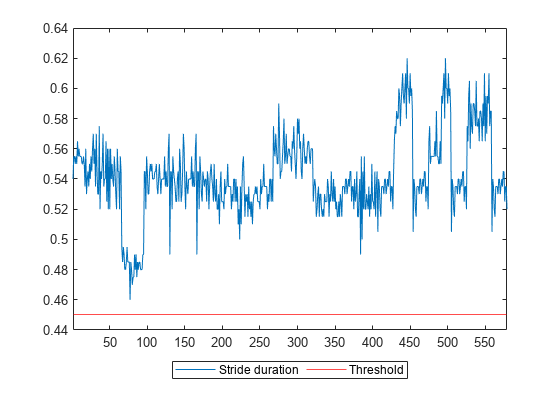

            if length(pks) < 2 % Missing peak
                pks(1) = NaN; pks(2) = NaN;
            elseif length(pks) == 3 % One peak too many
                pks(1) = [];
            end

            if length(ind) == 3 % One peak too many
                ind(1) = [];
            end

            if k == 1 || 2

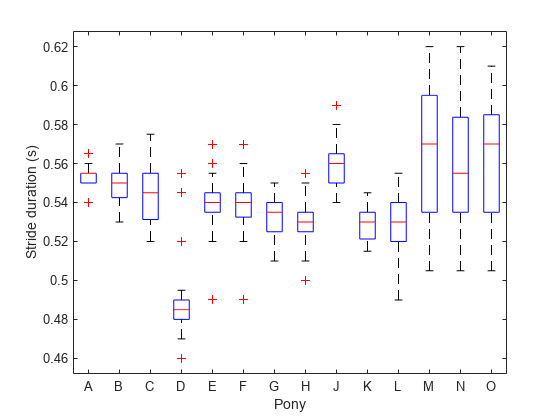

                MaxDiff(i,k) = pks(2) - pks(1);
                if length(ind) < 2
                    MinDiff(i,k) = NaN; 
                else
                    MinDiff(i,k) = strides{i,k}(ind(2)) - strides{i,k}(ind(1));
                end
                
            else
                MaxDiff(i,k) = pks(1) - pks(2);
                if length(ind) < 2
                    MinDiff(i,k) = NaN; 
                else
                    MinDiff(i,k) = strides{i,k}(ind(1)) - strides{i,k}(ind(2));
                end
            end
        end

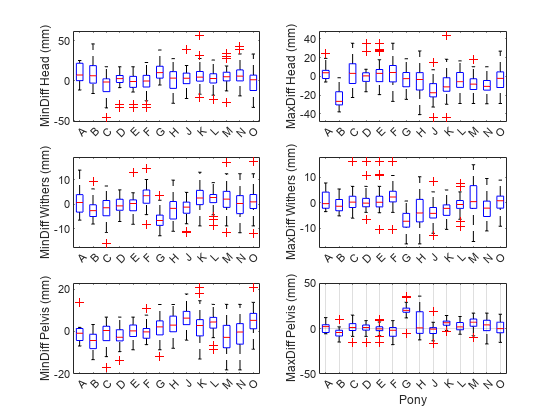

        StrideDuration(i) = Extracted_Time(changeIndices(i+1))-Extracted_Time(changeIndices(i));

%         for ii = 1:length(pks)
%             ind_temp(ii) = find(strides{i,k}==pks(ii));
%         end
%         plot(strides{i,k}); hold on
%         plot(ind_temp,pks,'vr');
%         plot(ind,strides{i,k}(ind),'^b'); pause; close; ind_temp = [];
    end

    for k = 1:3
        subplot(2,3,3+k)
        tplot = [MaxDiff(:,k),MinDiff(:,k)];
        cgr = [repmat({'MaxDiff'},1,length(MaxDiff(:,k))),...
            repmat({'Mindiff'},1,length(MinDiff(:,k)))];
        boxplot(tplot,cgr);
        ylim([-40 40]); yline(0,'r');
        title(MarkersNames{k}); ylabel('Asymmetry index (mm)'); grid on
    end

    %% Save the results
    temp = [StrideDuration',MinDiff(:,1),MaxDiff(:,1),...
                            MinDiff(:,2),MaxDiff(:,2),...
                            MinDiff(:,3),MaxDiff(:,3)];
    tempInfo = repmat([HorseID,TimePointsList(1)],length(MinDiff),1);
    temptable1 = array2table(temp);
    temptable2 = cell2table(tempInfo);

    temptable = [temptable1,temptable2];
    temptable.Properties.VariableNames  = {'StrideDuration',...

        'MinDiff_Head','MaxDiff_Head',...
        'MinDiff_Withers','MaxDiff_Withers',...
        'MinDiff_Pelvis','MaxDiff_Pelvis',...
        'HorseID','TimePoint'};

    results = [results;temptable];
%     pause;
%     clearvars -except results HorsesList TimePointsList files datapath segmentTimestamps MarkersUpperBody...
%         MarkersStrideSplit MarkersNames;
%     close all; clc;
end


## Clean the results

Here we first remove outliers based on the Stride Duration:

If you plot the values of all extracted stride durations, you will see that some have extremely low values. This is due to issues in stride split for example, or the horses doing what horses do. For futher analysis, we need to remove those. You can either set a threshold by looking at the data, by extracting descriptive statistics, or because a pony stride duration at trot on a treadmill cannot reasonnably be shorter than 0.4s.

close all;

figure
plot(results.StrideDuration)
toClean = find(results.StrideDuration < 0.45);
hold on;
yline(0.45,'r');
plot(toClean,results.StrideDuration(toClean),' or'); 
xlim('tight');
legend('Stride duration','Threshold','Outliers', ...
    'Orientation','horizontal','Location','southoutside');

results(toClean,:) = [];

We will also remove the strides for which it was not possible to calculate a parameter, for example if only one peak was found.

toClean = find(isnan(results.MinDiff_Withers) | isnan(results.MinDiff_Pelvis) | ...
    isnan(results.MaxDiff_Withers) | isnan(results.MaxDiff_Pelvis)); 
results(unique(toClean),:) = [];

Finally, we will save the results table

writetable(results,'./results/results_T0_AllHorses.csv')

## Plot

Now, we can plot the results and compare the horses.

We first need to reorganise the variables!

figure
boxplot(results.StrideDuration,categorical(results.HorseID));
ylabel('Stride duration (s)');
xlabel('Pony')
figure
ax(1) = subplot(321);
boxplot(results.MinDiff_Head,categorical(results.HorseID));
ylabel('MinDiff Head (mm)');

ax(2) = subplot(322);
boxplot(results.MaxDiff_Head,categorical(results.HorseID));
ylabel('MaxDiff Head (mm)');

ax(3) = subplot(323);
boxplot(results.MinDiff_Withers,categorical(results.HorseID));
ylabel('MinDiff Withers (mm)');

ax(4) = subplot(324);
boxplot(results.MaxDiff_Withers,categorical(results.HorseID));
ylabel('MaxDiff Withers (mm)');

ax(5) = subplot(325);
boxplot(results.MinDiff_Pelvis,categorical(results.HorseID));
ylabel('MinDiff Pelvis (mm)');

ax(6) = subplot(326);
boxplot(results.MaxDiff_Pelvis,categorical(results.HorseID));
ylabel('MaxDiff Pelvis (mm)'); 

for i = 1:6
    ax(i); 
    set(ax(i),"YLim",[-60 60],'YGrid','on');
    ax(i).XLabel.String = 'Pony';
end